# Modifying the stream network

## Background

Analyses of stream networks often require that the extent and geometry of the stream network is modified so that it covers an area of interest. For example, applications may be interested to compare the stream network up- and downstream of a fault line. Other applications may wish to remove those parts of the stream network that extend into the alluvial part of the landscape. TopoToolbox contains a number of functions that allow the modification of stream networks. Some of these tools are interactive GUIs.

## Load data and set default colors

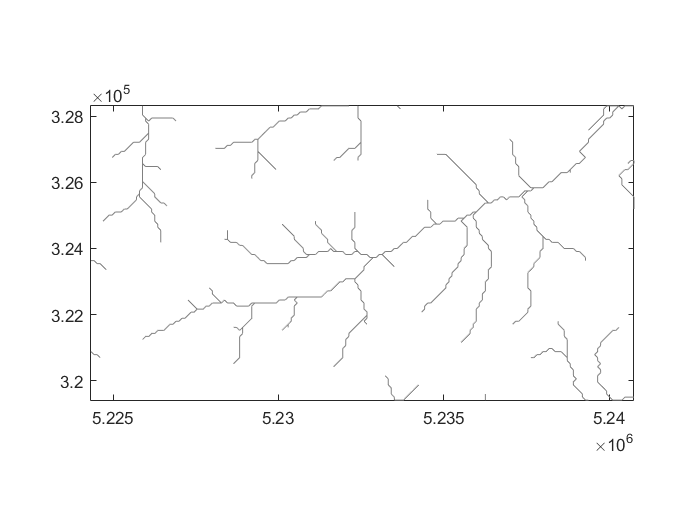

load exampleDEM.mat
DEM = GRIDobj(Y',X',dem');
FD  = FLOWobj(DEM);
S   = STREAMobj(FD,'minarea',100);
c1   = [.5 .5 .5];
c2   = 'r';
lw   = 1.5;
plot(S,'color',c1);
axis image

## Extract connected components

Connected components are parts of the stream network that form individual trees or catchments. The function klargestconncomps extracts the number k largest connected components. Here, the term largest refers to the number of nodes in each connected component, i.e. the number of river pixels.

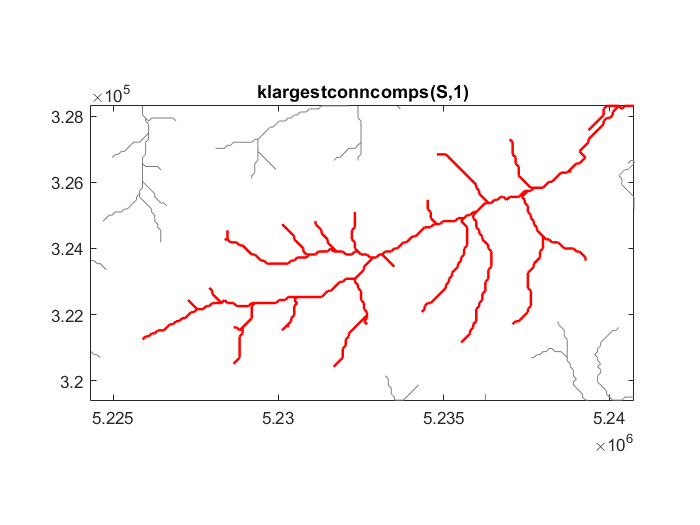

plot(S,'color',c1);
hold on
S2 = klargestconncomps(S,1);
plot(S2,c2,'LineWidth',lw);
axis image
title('klargestconncomps(S,1)');
hold off

## Remove short streams

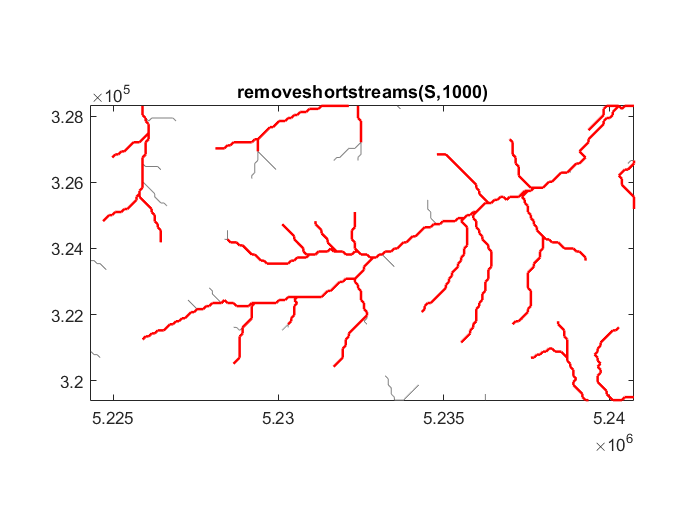

plot(S,'color',c1);
hold on
S2 = removeshortstreams(S,1000);
plot(S2,c2,'LineWidth',lw);
axis image
title('removeshortstreams(S,1000)');
hold off

## Extract the trunk stream

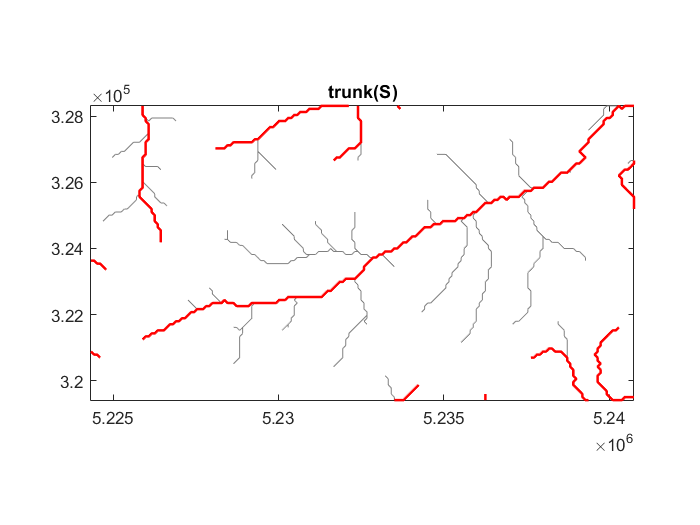

plot(S,'color',c1);
hold on
S2 = trunk(S);
plot(S2,c2,'LineWidth',lw);
axis image
title('trunk(S)');
hold off

## Trim network to specific distance

By default, distance is measured as distance from the outlet. The function modify with the option 'distance' allows you to trim the network to a certain distance range. 

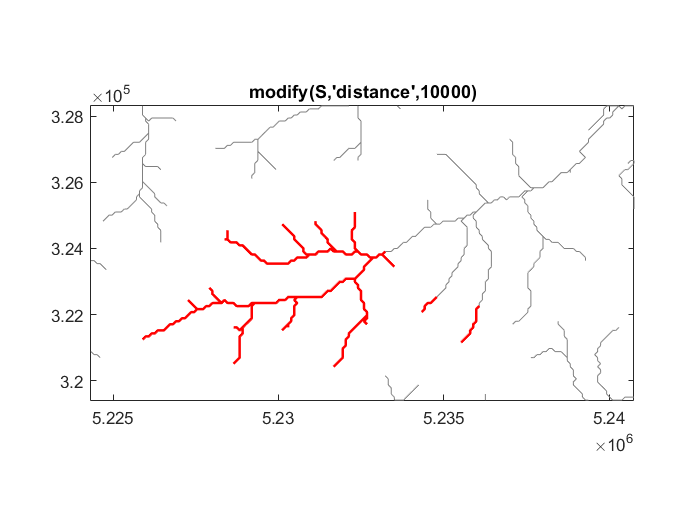

plot(S,'color',c1);
hold on
S2 = modify(S,'distance',10000);
plot(S2,c2,'LineWidth',lw);
axis image
title('modify(S,''distance'',10000)');
hold off

The parameter value following the parameter name 'distance' can also be a two-element vector of distances that bracket the distances of the stream network to be extracted.

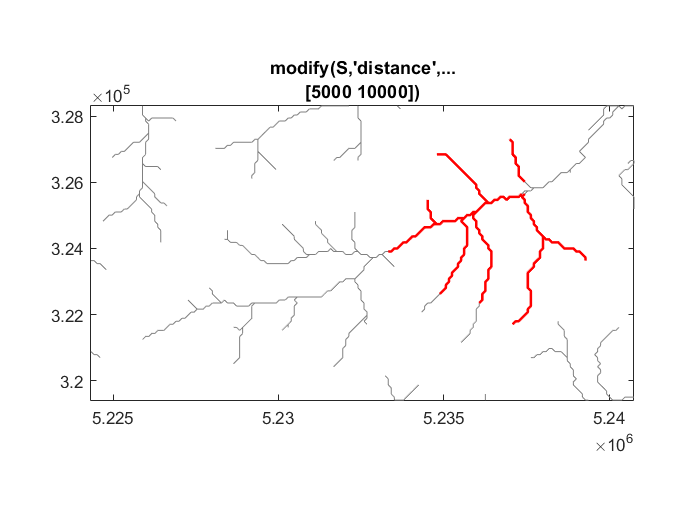

plot(S,'color',c1);
hold on
S2 = modify(S,'distance',[5000 10000]);
plot(S2,c2,'LineWidth',lw);
axis image
title({'modify(S,''distance'',...';'[5000 10000])'});
hold off

## Extract streams with specific stream order

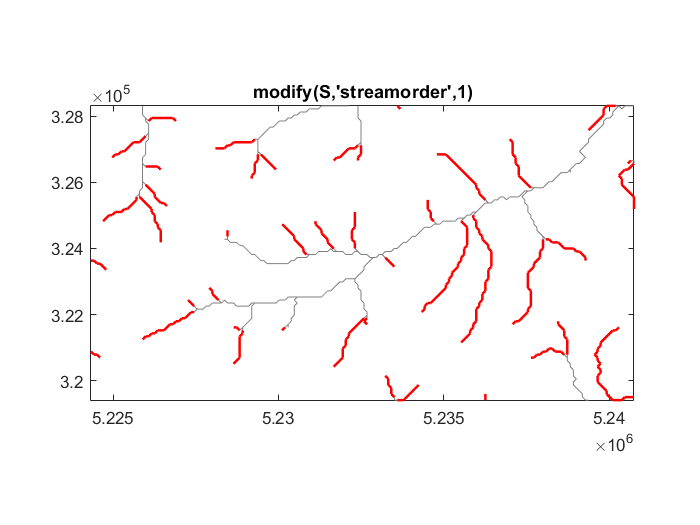

plot(S,'color',c1);
hold on
S2 = modify(S,'streamorder',1);
plot(S2,c2,'LineWidth',lw);
axis image
title('modify(S,''streamorder'',1)');
hold off

The parameter value for the option 'streamorder' also takes logical expressions as the following:

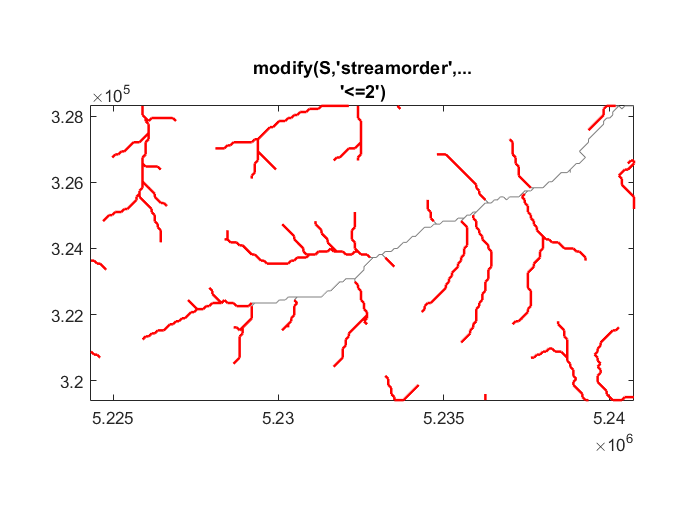

plot(S,'color',c1);
hold on
S2 = modify(S,'streamorder','<=2');
plot(S2,c2,'LineWidth',lw);
axis image
title({'modify(S,''streamorder'',...';'''<=2'')'});
hold off

## Extract upstream or downstream stream network

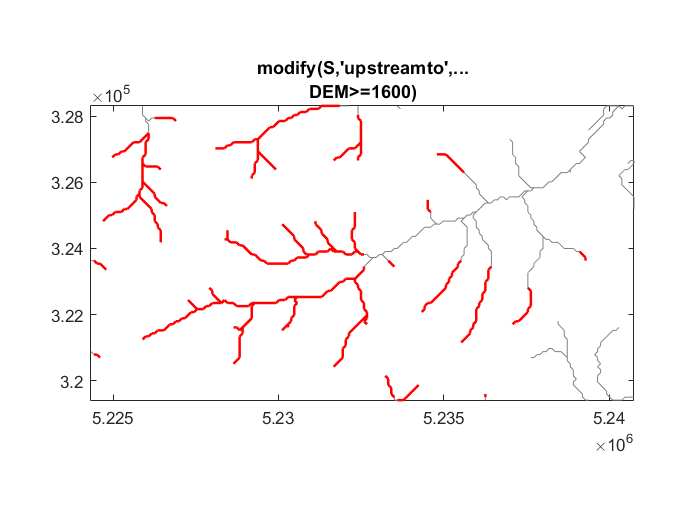

plot(S,'color',c1);
hold on
S2 = modify(S,'upstreamto',DEM>=1600);
plot(S2,c2,'LineWidth',lw);
axis image
title({'modify(S,''upstreamto'',...';'DEM>=1600)'});
hold off

or

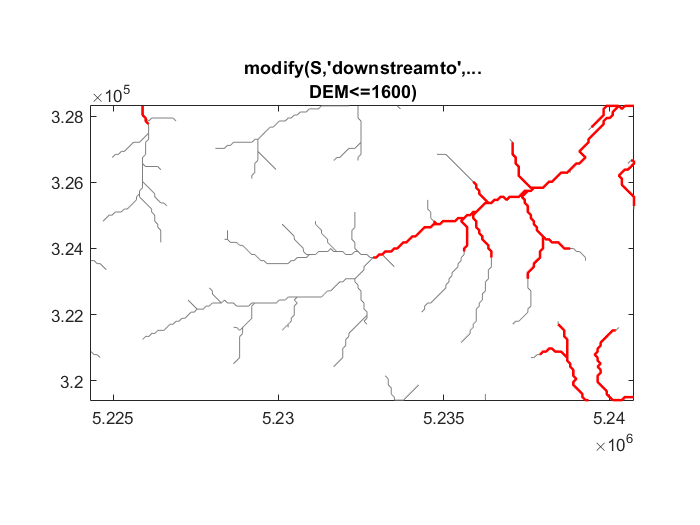

plot(S,'color',c1);
hold on
S2 = modify(S,'downstreamto',DEM<=1600);
plot(S2,c2,'LineWidth',lw);
axis image
title({'modify(S,''downstreamto'',...';'DEM<=1600)'});
hold off

## Extract tributaries

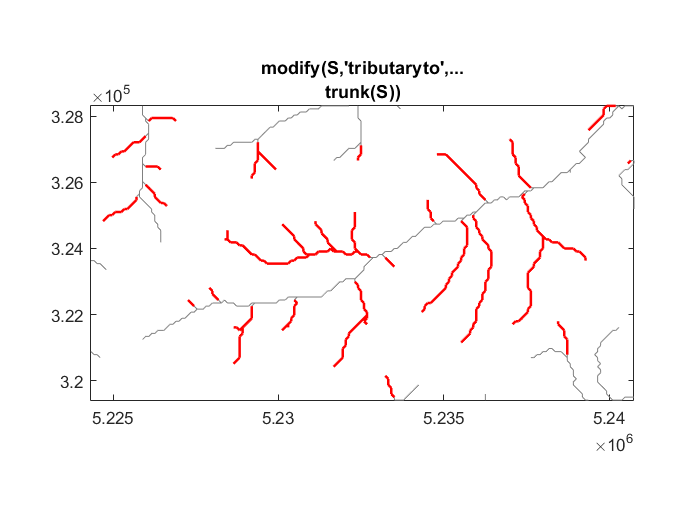

plot(S,'color',c1);
hold on
S2 = modify(S,'tributaryto',trunk(S));
plot(S2,c2,'LineWidth',lw);
axis image
title({'modify(S,''tributaryto'',...';'trunk(S))'});
hold off

## Interactive tools

TopoToolbox contains a number of GUIs that can be used to interactively modify the stream network:

- The function `modify` with the parameter 'interactive' set to 'polyselect' or 'reachselect'.

- The function `extractconncomps`

- The function `flowpathapp` 